## 8.6   符号方程与求解

### 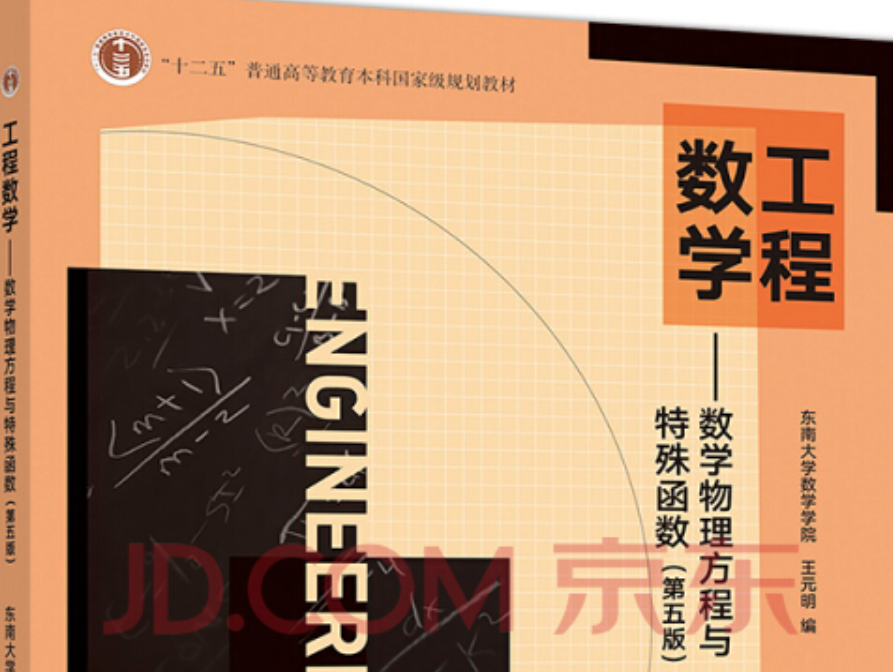

包括简单方程的求解：多元一次方程、线性方程组：使用函数**solve**

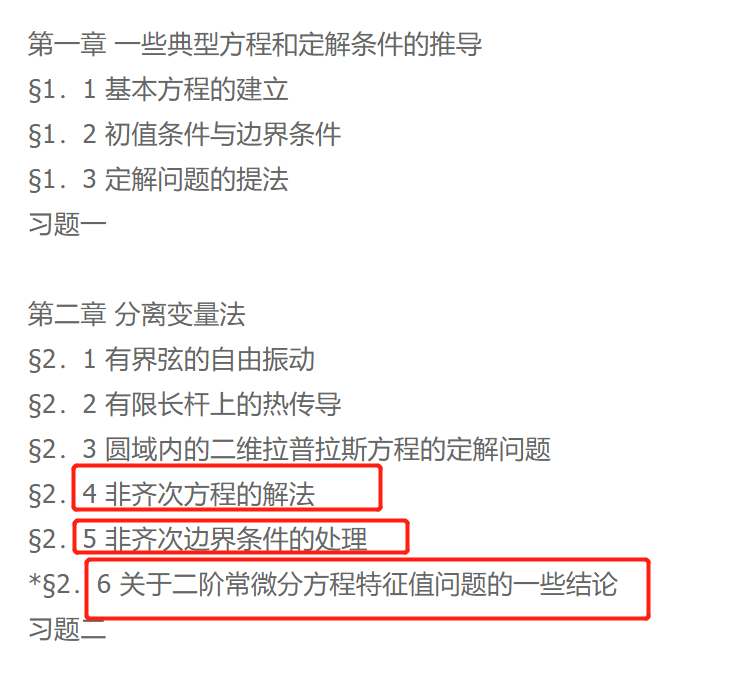，微分方程组： 使用函数**dsolve**

### **8.6.1   符号代数方程求解**

代数方程包括线性方程、非线性方程和超越方程等。

**1．解代数方程**

在MATLAB 中， solve() 函数用于求解代数方程和方程组，其调用格式如下：

- g = solve(eq) 。对默认自变量 x 求解，求方程符号eq 的解，输入参数 eq 可以是符号表达式或字符串，即 solve(eq) 对方程 eq 中的默认变量 x ，求解方程 eq=0 。若输出参量g 为单一变量，则对于有多重解的非线性方程， g 为一行向量。

- solve(eq,var,value) 。求解方程  eq  的解，对指定自变量 var 求解。例如 g=solve(x^2-1)  或 g=solve(x^2-1,x,0)  或g=solve(x^2-1,0) 。

对于单个方程的情况，返回结果为一个符号表达式，或是一个符号表达式组成的数组。

## **例  求一元二次方程 **${\textrm{ax}}^2 +\textrm{bx}+c=0$** 的根。**

解  程序如下：

syms a b c x
f=a*x^2+b*x+c

$$f = a\,x^{2}+b\,x+c$$

solve(f)

$$ans = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$

即方程 ${\textrm{ax}}^2 +\textrm{bx}+c=0$ 的根为$x = \frac{{ - b \pm \sqrt {{b^2} - 4ac} }}{{2a}}$

`如果把a作为自变量求解，则结果如下：`

solve(f, a)

ans= - (b*x+c)/x^2

**2 ．代数方程组的符号解法**

代数方程组同样使用 solve() 函数进行求解。

对于方程组的情况，返回结果为一个结构体，结构体的元素为每个变量对应的表达式，各个变量按照字母顺序排列，其格式如下：

- solve(eq1,eq2,...,eqn) 。求由方程 eq1 、 eq2 、…、eqn 等组成的系统，自变量为默认自变量；

- solve(eq1,eq2,...,eqn,var1,var2,...,varn) 。求由方程 eq1 、 eq2 、…、 eqn 等组成的系统，自变量为指定的自变量： var1 、 var2 、…、 varn 。

## 例  求 $\left\{ \begin{array}{l}
x + y = 1\\
x - 11y = 5
\end{array} \right.$   的解。

解  程序如下：

syms x y
f1 = x+y-1

$$f1 = x+y-1$$

f2 = x-11*y-5

$$f2 = x-11\,y-5$$

S = solve(f1,f2)

S = 包含以下字段的 struct :
    x: [1×1 sym]
    y: [1×1 sym]


S.x        

S.y     

### **8.6.2   常微分方程的解析解**

#### 1 ．常微分方程的求解

常微分方程解析解的求解法，一般有以下三种。

**1)  积分求解**

有些微分方程可直接通过积分求解，例如通过一阶常系数常微分方程：

## 
$$\frac{{dy}}{{dt}} = y + 1$$


化为

## 
$$$\frac{{dy}}{{y + 1}} = dt$$$


两边积分

## 
$$\int\frac{{dy}}{{y + 1}} = \int dt
\leftrightarrow \ln(y+1) =t+c_1\leftrightarrow y=c e^t - 1$$


即，通解为

## 
$$y={\textrm{ce}}^t -1$$


其中， *c*为任意常数。

有些常微分方程可用一些技巧，如分离变量法、积分因子法、常数变异法、降阶法等可化为可积分的方程而求得解析解。

**2)  求特解和通解**

线性常微分方程的解满足叠加原理，求解可归结为求一个特解和相应齐次微分方程的通解，一阶以及高阶变系数线性微分方程总可用这一思路求得显式解。

**例：二阶常系数线性微分方程**

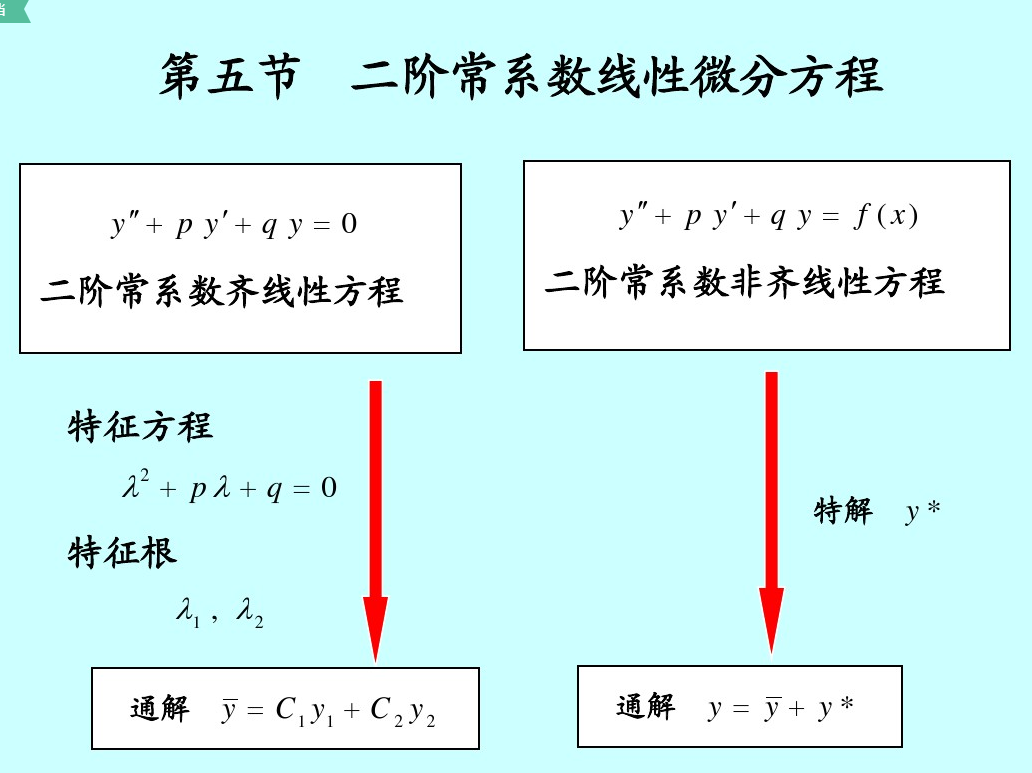

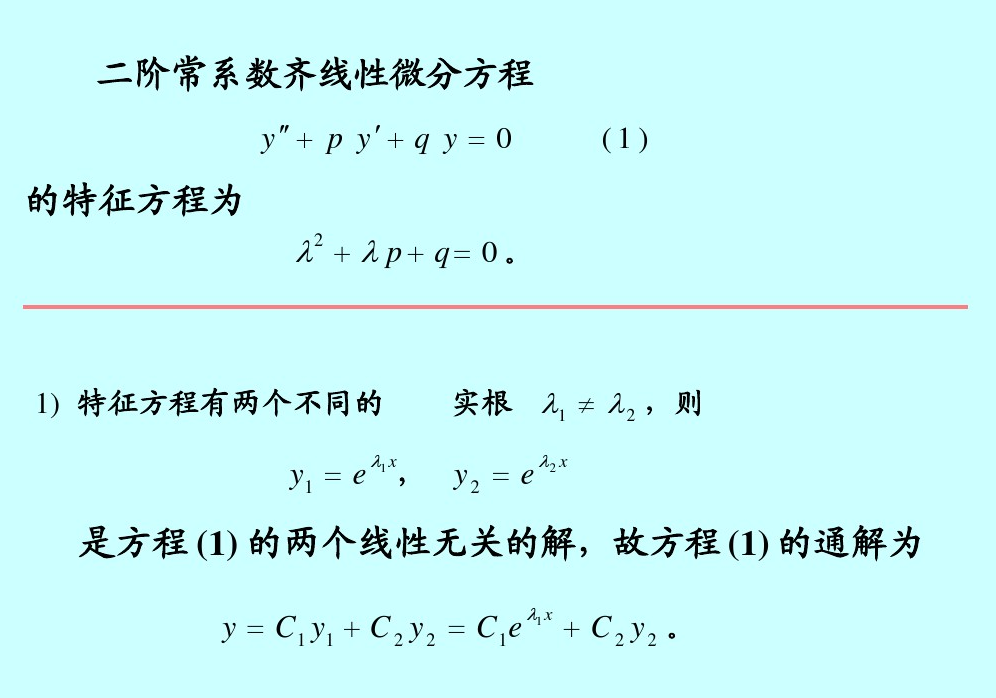

**例：三阶常系数线性微分方程**

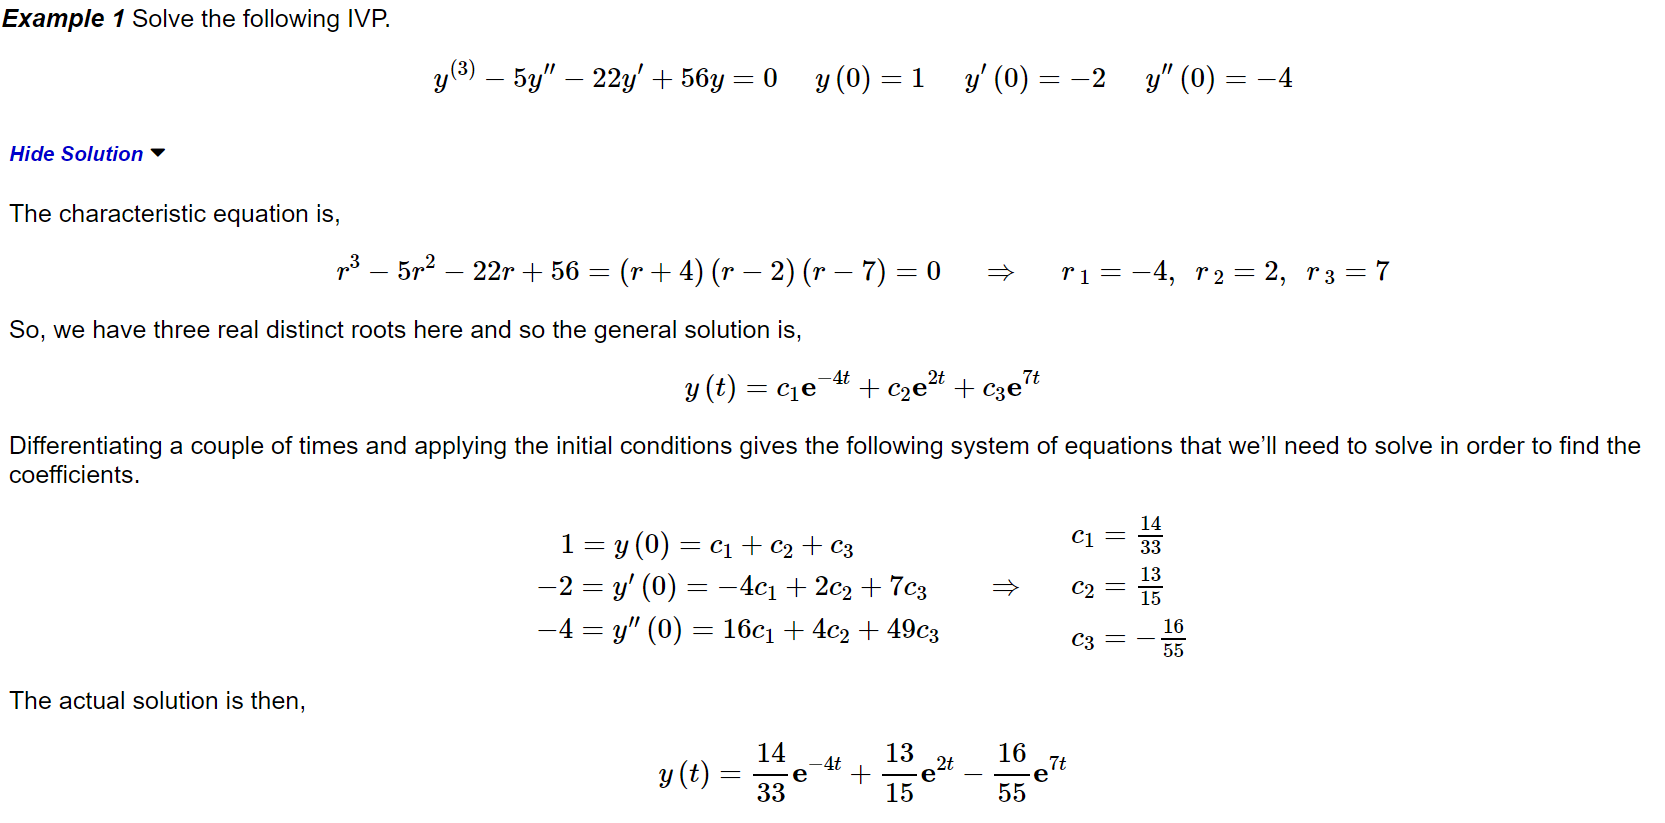

**3)  求高阶线性常系数微分方程的基本解和特解**

高阶线性常系数微分方程可用特征根法求得相应齐次微分方程的基本解，再用常数变异法求特解。一阶常微分方程与高阶微分方程可以互化，已给一个 *n*阶方程

## 
$$y(n) = f(t, y', y", \dots , y^{(n-1)})$$


$n$阶微分方程通解的一般形式为

## 
$$$y = \phi (x,{c_1}, \cdots ,{c_n})$$$


其中，$${c_1}, \cdots ,{c_n}$$为相互独立的任意常数。

MATLAB 中符号常微分方程使用 dsolve() 函数进行求解，具体调用格式如下：

(1)  r = dsolve('eq1','eq2', …,'cond1','cond2',...,'v') 。其中 eq1 、 eq2 等表示待求解的方程， v 是指定的自变量，如果不指定自变量，那么默认的自变量为 x ，也可任意指定自变量为 't' 、'u' 等。 cond1 、 cond2  等表示初始值，通常表示为 y(a) = b 或者 diff(a) = b 。如果不指定初始值，或者初始值方程的个数少于因变量的个数，则最后得到的结果中会包含常数项，表示为 C1 、 C2  等。 dsolve() 函数最多可接受 12 个输入参数。

(2)  [y1,y2…]=dsolve(x1,x2,…xn)。  返回微分方程的解。

## 例     求微分方程：$$\frac{{dx}}{{dt}} =  - ax$$和$$\frac{{{d^2}x}}{{d{t^2}}} =  - ax$$

解   语法如下：

syms a x(t);
eqn1 = diff(x,t) == -a*x;
s1 = dsolve(eqn1)

$$s1 = C_{1}\,{\mathrm{e}}^{-a\,t}$$

eqn2 = diff(x,t,2) == -a*x;
s2 = dsolve(eqn2)

$$s2 = C_{1}\,{\mathrm{e}}^{\sqrt{-a}\,t}+C_{2}\,{\mathrm{e}}^{-\sqrt{-a}\,t}$$

结果为：

s1 =

C1*exp(-a*t)

s2 =

C1*exp((-a)^(1/2)*t) + C2*exp(-(-a)^(1/2)*t)

## 例     求微分方程 $y\prime =x$ 的通解。

解   程序如下：

syms x y(x)    %定义x， y 为符号
eqn1 = diff(y) == x;
y = dsolve(eqn1)

$$y = \frac{x^{2}}{2}+C_{1}$$

`结果为：`

y =

x^2/2 + C1

## 例    求微分方程 $\[\left\{ \begin{array}{l}
y'' = x + y'\\
y(0) = 1,{\rm{  }}y'(0) = 0
\end{array} \right.\]$的特解。

解   程序如下：

syms x y(x)
eqn = diff(y,x,2) == x + diff(y,x);
Dy = diff(y);
cond = [y(0) == 1, Dy(0) == 0];
S = dsolve(eqn,cond)

$$S = {\mathrm{e}}^{x}-x-\frac{x^{2}}{2}$$

结果是：

S =

exp(x) - x - x^2/2

## 应用题举例 [1]：

一敌舰在某海域内沿着正北方向航行时，我方战舰恰好位于敌舰的正西方向1 公里处。我舰向敌舰发射制导鱼雷，敌舰速度为0.42 公里/分，鱼雷速度为敌舰速度的2倍。试问敌舰航行多远时将被击中？

[1] 参考上财微分方程课程讲义：[http://course.shufe.edu.cn/ode/skja_ch4.pdf](http://course.shufe.edu.cn/ode/skja_ch4.pdf)

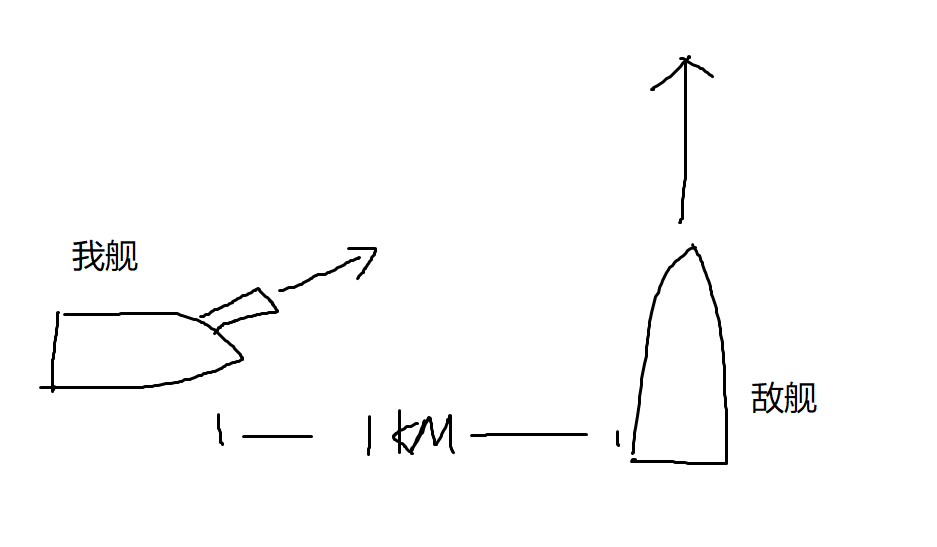

解 

设敌舰初始点在$Q_0 \left(1,0\right)$ 处，运动方向为平行y 轴的直线，$t$时刻到达$Q$点，鱼雷的初始点在$P_0 \left(0,0\right)$处，沿曲线$y=y\left(x\right)$追击，敌舰的速度$v_0 =0\ldotp 42$，则在时刻t ，鱼雷在点$P\left(x,y\right)$处，此时敌舰在点$Q\left(1,v_0 t\right)$。由于鱼雷在追击过程中始终指向敌舰，而鱼雷的运动方向正好是沿曲线$y=y\left(x\right)$的切线方向，那么，鱼雷的运动方程为

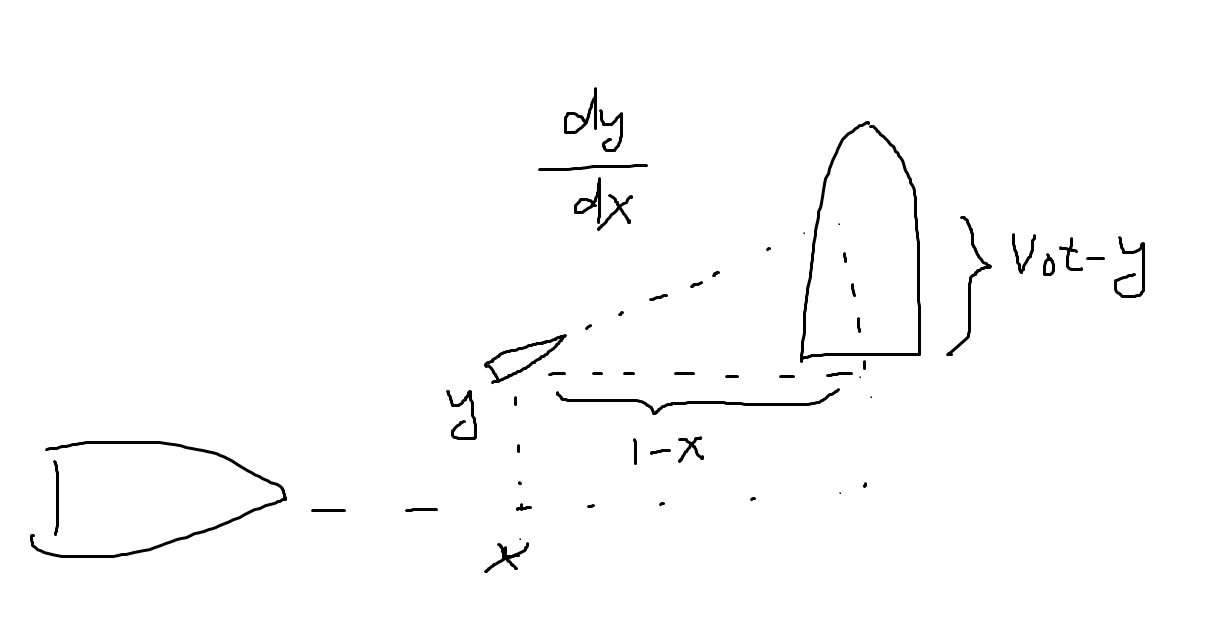

## $\frac{d y}{d x}=\frac{v_{0} t-y}{1-x}$        （1）

而鱼雷行使的速度为$2v_0$，分为水平方向运动和垂直方向运动，故满足以下关系式

## $\sqrt{\left(\frac{d x}{d t}\right)^{2}+\left(\frac{d y}{d t}\right)^{2}}=2 v_{0}$        （2）

将(1)改写为

## $v_{0} t-y=(1-x) \frac{d y}{d x}$        （3）

将(3)两边同时对x求导数，得

## $v_{0} \frac{d t}{d x}-\frac{d y}{d x}=(1-x) \frac{d^{2} y}{d x^{2}}-\frac{d y}{d x}$        （4）

由(2)可得

## $\frac{d t}{d x}=\frac{1}{2 v_{0}} \sqrt{1+\left(\frac{d y}{d x}\right)^{2}}$        （5）

将(5)代入(4)中，得

## $\left\{\begin{array}{l}
\frac{d^{2} y}{d x^{2}}=\frac{\sqrt{1+\left(\frac{d y}{d x}\right)^{2}}}{2(1-x)} \\
y(0)=0, y^{\prime}(0)=0
\end{array}\right.$        （6）

(6)就是一个带有初始条件的二阶微分方程。如果能求出这个方程的解，就可以解决敌舰航行多远时被击中这样的问题了。

解   程序如下：

syms x y(x)
eqn = diff(y,x,2) == sqrt(1 + (diff(y,x))^2)/(2*(1-x))

$$eqn(x) = \frac{\partial^{2}}{\partial x^{2}}y\left(x\right)=-\frac{\sqrt{{\left(\frac{\partial }{\partial x}y\left(x\right)\right)}^{2}+1}}{2\,x-2}$$

Dy = diff(y,x)

$$Dy(x) = \frac{\partial }{\partial x}y\left(x\right)$$

cond = [y(0) == 0, Dy(0) == 0];
S = dsolve(eqn,cond);
x = sym(1);
eval(S)

$$ans = \frac{2}{3}$$

#### 2 ．微分方程组的求解

微分方程组通过 dsolve() 函数进行求解，格式为：

r = dsolve(eq1,eq2,..., cond1,cond2,..., v)

该语句求解由参数 eq1 、 eq2 等指定的方程组成的系统，初值条件为 cond1 、 cond2 等， v 为自变量

## 例     求微分方程组$$\left\{ \begin{array}{l}
x' = x + y\\
y' = 2x
\end{array} \right.$$ 的通解。

解   程序如下：

syms x(t) y(t)
eqn1 = diff(x,t) == y + x;
eqn2 = diff(y,t) == 2 * x;
[x y] = dsolve(eqn1,eqn2)

$$x = C_{1}\,{\mathrm{e}}^{2\,t}-\frac{C_{2}\,{\mathrm{e}}^{-t}}{2}$$

$$y = C_{1}\,{\mathrm{e}}^{2\,t}+C_{2}\,{\mathrm{e}}^{-t}$$

结果为

x = -  1/2*C1*exp(-  t)+C2*exp(2*t)

y =C1*exp(-  t)+C2*exp(2*t)

## 例  求微分方程组：$$\left\{ \begin{array}{l}
u' = v\\
v' = w\\
w' =  - u
\end{array} \right.$$， $u\left(0\right)=0,\;v\left(0\right)=0,\;w\left(0\right)=1$ 的结果。

解  程序如下：

syms u(t) v(t) w(t);
eqn = [diff(u) == v, diff(v) == w, diff(w) == -u];
cond = [u(0) == 0; v(0) == 0; w(0) == 1];
S = dsolve(eqn, cond)

S = 包含以下字段的 struct :
    v: [1×1 sym]
    u: [1×1 sym]
    w: [1×1 sym]


结果为一个结构：

S = 

u: [1x1 sym]

v: [1x1 sym]

w: [1x1 sym]

可用查询结构成员的方法，查询结果：

S.u

$$ans = \frac{{\mathrm{e}}^{-t}}{3}-\frac{\cos\left(\frac{\sqrt{3}\,t}{2}\right)\,\sqrt{{\mathrm{e}}^{t}}}{3}+\frac{\sqrt{3}\,\sin\left(\frac{\sqrt{3}\,t}{2}\right)\,\sqrt{{\mathrm{e}}^{t}}}{3}$$

ans =

1/(3*exp(t)) -

(cos((3^(1/2)*t)/2)*exp(t)^(3/2))/(3*exp(t))

+ (3^(1/2)*sin((3^(1/2)*t)/2)*exp(t)^(3/2))/(3*exp(t))

## 8.7   符号函数图形绘制

### 8.7.1   符号函数二维绘图函数 fplot()

1 ．显函数的调用

对于显函数，其调用格式如下：

- fplot(f) 。绘制函数 f 在区间 (-5≤x≤5) 内的图形， f 可以是函数句柄或串。

- fplot(f,[min,max]) 。绘制函数 f 在指定区间 [min, max]内的图形。

2 ．隐函数的调用

隐函数定义为 fun2(x,y) ， fplot() 函数的调用格式如下：

- fplot(fun2) ：绘制函数 fun2(x,y)=0 在区间(-5≤x≤5)的图形。

- fplot(fun2,[TMIN TMAX]) ：绘制函数 fun2(x,y)=0， x(t) 和 y(t) 的取值范围由 tmin < t < tmax 决定。

## 例   MATLAB 中符号计算中提供单位阶跃函数 heaviside(t-a) 、斜坡可以使用阶跃和直线方程构成。

解   (1)  绘制a=4 时的阶跃函数。

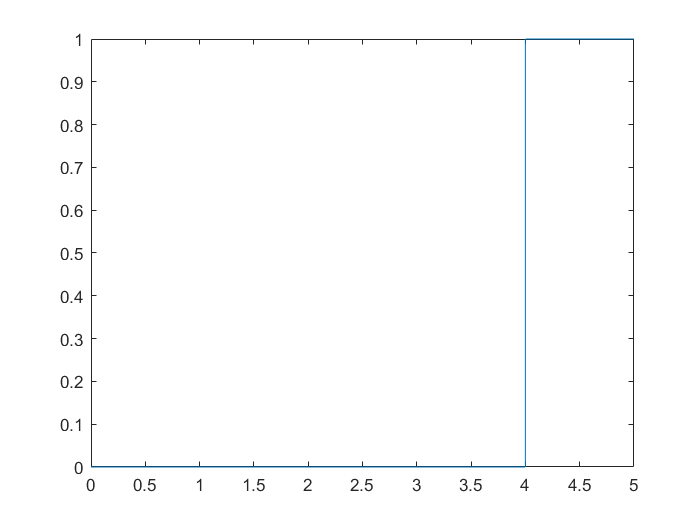

f=@(t)heaviside(t-4);
fplot(f,[0 5]) %

(2)  在t=1 时发生转折斜率为 1 的斜坡可以表示为

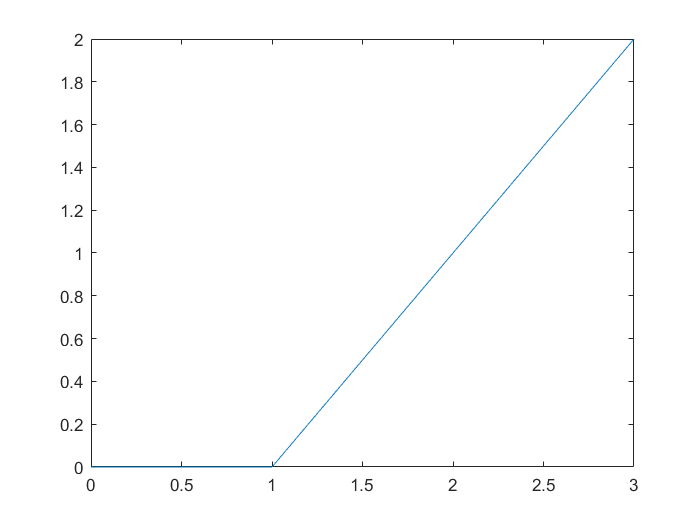

f=@(t)t.*heaviside(t-1)-heaviside(t-1);
fplot(f,[0 3])

绘制出斜坡函数曲线。

3 ．参数方程的调用

对于参数方程， fplot() 函数的调用格式有：

- fplot(x,y) ：绘制参数方程 x = x(t) 、 y = y(t) 在 (0 <t < 2 ）的曲线。

- fplot(x,y,[tmin,tmax]) ：绘制参数方程  x = x(t) 、 y= y(t) 在tmin < t < tmax 的曲线。

### **8.7.2   符号函数三维绘图函数 fplot3()**

fplot3() 函数用于绘制三维参数曲线。该函数的调用格式如下：

- fplot3(x,y,z) 。在默认区间 (0<t <2p  内绘制参数方程x = x(t) 、 y = y(t)、 z = z(t) 的图像。

- fplot3(x,y,z,[tmin,tmax]) 。在区间 tmin<t<tmax 内绘制参数方程 x = x(t) 、 y = y(t) 、 z = z(t)  的图像。

## 例   绘制空间曲线的动态轨迹。

解  程序如下：

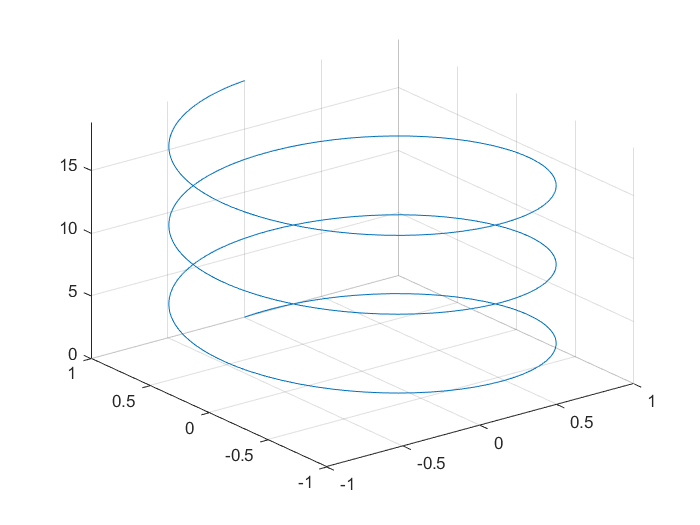

syms x y t z
x= sin(t);y= cos(t);z=t;
fplot3(x,y,z,[0,6*pi])

生成空间曲线的动态轨迹。

### 8.7.3   符号函数曲面网格图及表面图的绘制

1 ． fmesh() 、 fsurf() 函数

fmesh() 、 fsurf() 函数分别用于绘制三维网格图和三维表面图。这两个函数的用法相同，下面以函数 ezmesh() 函数为例介绍三维曲面的绘制。该函数的调用格式如下：

- fmesh(f) ：绘制函数 f(x,y) 在默认区域 -5≤x≤5 、-5≤y≤5内的图像。

- fmesh(f,domain) ：在 domain 指定区域绘制函数 f(x,y) 的图像；

- fmesh(x,y,z) ：在默认区域 -5≤s≤5 、-5≤t≤5 内，绘制三维参数方程 x = x(s,t) ， y = y(s,t) ， and z = z(s,t) 的图形。

- fmesh(x,y,z,[smin,smax,tmin,tmax]) 或fmesh(x,y,z,[min,max]) ：在指定区域绘制三维参数方程的图像。

## 例 已知函数$$f(x,y) = x{e^{ - {x^2} - {y^2}}}$$，绘制三维网格图。

解  程序如下：

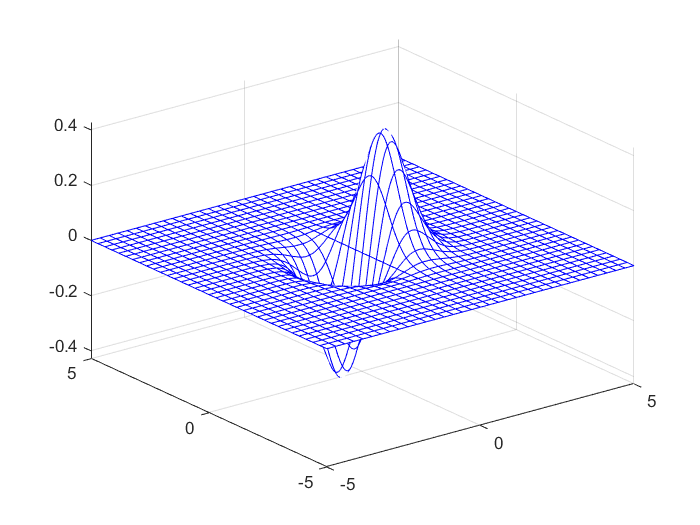

syms x y
fh = @(x,y) x.*exp(-x.^2-y.^2);
fmesh(fh)
colormap([0 0 1])

绘制出的三维网格图。

## 工程实例——储油罐的油量计算

问题：一平放的椭圆柱形状的油罐，长度为 L ，椭圆的长半轴为a ，短半轴为b ，油的密度为 ρ ，油罐中油的高度为h 。油罐的横断面如图所示。

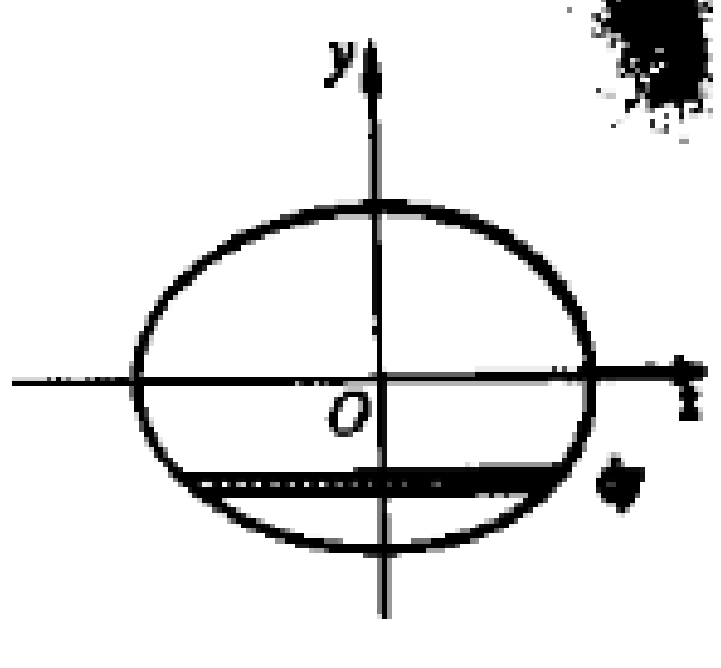

解题思路：

- 将横断面的方程表达式列出：$$\frac{{{x^2}}}{{{a^2}}} + \frac{{{y^2}}}{{{b^2}}} = 1$$

- 宽度x是高度y的函数，x(y)：$x = 2\left(a\sqrt{1-\frac{y^2}{b^2}}\right)=2a\sqrt{1-\frac{y^2}{b^2}}$

- 在高度y处寻找$\textrm{dy}$，则图中小矩形的面积为$$2a\sqrt {1 - \frac{{{y^2}}}{{{b^2}}}} dy$$

- 油罐中油横断面中高度为 h 时的面积为$$\int_{ - b}^{ - b + h} {2a\sqrt {1 - \frac{{{y^2}}}{{{b^2}}}} dy} $$

- 油量为$$\int_{ - b}^{ - b + h} {2\rho La\sqrt {1 - \frac{{{y^2}}}{{{b^2}}}} dy} $$

- 对油量进行积分得到

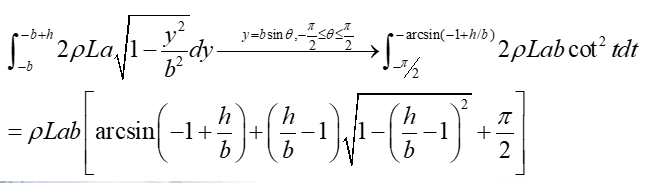

代码实现：

clear,clc,close all;
syms a b h y L r;
m = sqrt(b^2-y^2);
m2 = int(m,y,-b,-b+h)

$$m2 = \frac{b^{2}\,\mathrm{asin}\left(\frac{b}{\sqrt{b^{2}}}\right)}{2}-\frac{b^{2}\,\mathrm{asin}\left(\frac{b-h}{\sqrt{b^{2}}}\right)}{2}-\frac{\sqrt{b^{2}-{\left(b-h\right)}^{2}}\,\left(b-h\right)}{2}$$

S = 2*a/b*m2

$$S = -\frac{2\,a\,\left(\frac{b^{2}\,\mathrm{asin}\left(\frac{b-h}{\sqrt{b^{2}}}\right)}{2}-\frac{b^{2}\,\mathrm{asin}\left(\frac{b}{\sqrt{b^{2}}}\right)}{2}+\frac{\sqrt{b^{2}-{\left(b-h\right)}^{2}}\,\left(b-h\right)}{2}\right)}{b}$$

V = S*L*r

$$V = -\frac{2\,L\,a\,r\,\left(\frac{b^{2}\,\mathrm{asin}\left(\frac{b-h}{\sqrt{b^{2}}}\right)}{2}-\frac{b^{2}\,\mathrm{asin}\left(\frac{b}{\sqrt{b^{2}}}\right)}{2}+\frac{\sqrt{b^{2}-{\left(b-h\right)}^{2}}\,\left(b-h\right)}{2}\right)}{b}$$

V1 = subs(V,sqrt(b^2),b)

$$V1 = -\frac{2\,L\,a\,r\,\left(\frac{b^{2}\,\mathrm{asin}\left(\frac{b-h}{b}\right)}{2}-\frac{\pi \,b^{2}}{4}+\frac{\sqrt{b^{2}-{\left(b-h\right)}^{2}}\,\left(b-h\right)}{2}\right)}{b}$$

simplify(V1)

$$ans = -\frac{2\,L\,a\,r\,\left(\frac{b^{2}\,\mathrm{asin}\left(\frac{b-h}{b}\right)}{2}-\frac{\pi \,b^{2}}{4}+\frac{\left(b-h\right)\,\sqrt{h\,\left(2\,b-h\right)}}{2}\right)}{b}$$

**作业**

1 、肿瘤大小分析

肿瘤大小 V 生长的速率与 V 的a 次方成正比，其中 a 为形状参数，0<=a<=1 ；而比例系数 K 随时间减小，减小速率又与当时的 K 值成正比，比例系数为环境系数 b 。设某肿瘤参数 a=1,b=0.1 ， K 的初始值为 2，V 的初始值为 1.

（ 1 ）请分析此肿瘤生长不会超过多大？（ 2 ）画图分析肿瘤大小 V 和

K 随时间变化趋势进行分析；（ 3 ）多长时间肿瘤大小翻一倍？（ 4 ）

肿瘤生长速率由递增转为递减的时间？

结题思路：首先建立肿瘤生长数学模型，然后对微分方程进行求解。


$$$\left\{ \begin{array}{l}
\frac{{dv}}{{dt}} = k{v^a}\\
\frac{{dk}}{{dt}} =  - bk
\end{array} \right.$$$
